# Initialization

clear all;

% accel data
accelerometer = load("acc_run1.mat");
% a2 = load("acc_run2.mat");
sampling = accelerometer.samples_per_second;
data_length = length(accelerometer.channels{1}.data);
channel_nbr = length(accelerometer.channels);
t = linspace(0, data_length/2, data_length) / 1000;

% cued data
cued_data = load('1330_1_2021_Jul_13_1449_V_cued_r_time.mat');
cued_data.stimonset = round(cued_data.stimonset * 1000);
cued_data.presstime = round(cued_data.presstime * 1000);

% FFT
fft_raw = zeros(data_length, length(accelerometer.channels));
for i = 1:length(accelerometer.channels)
    fft_raw(:, i) = abs(fft(accelerometer.channels{i}.data)).^2 ./ data_length;
end

f = (1:length(fft_raw)) * sampling / length(fft_raw);

% Raw signal
cutoff_low = 1; 
cutoff_high = 300; 
filter_order = 1;

[b, a] = butter(filter_order, [cutoff_low/(sampling/2), cutoff_high/(sampling/2)], 'bandpass');

raw = zeros(data_length, channel_nbr);
for i = 1:channel_nbr
    raw(:,i) = filtfilt(b, a , accelerometer.channels{i}.data);
end

# Isolating the movement

cutoff_low = 1; 
cutoff_high = 10; % around maximum of non trained human movement
% filter_order = 3; % makes it a lot less intuitive
filter_order = 1;

[b, a] = butter(filter_order, [cutoff_low/(sampling/2), cutoff_high/(sampling/2)], 'bandpass');

movement = zeros(data_length, channel_nbr);
for i = 1:channel_nbr
    movement(:,i) = filtfilt(b, a , accelerometer.channels{i}.data);
end

% TKEO https://www.ncbi.nlm.nih.gov/pmc/articles/PMC2945630/
window_size = 0.05*sampling;
[tkeo_movement, tkeo_movement_envelope] = getCleanSignal_tkeo(movement, window_size, channel_nbr);

% Enveloping with filtering
filter_order = 3;
cutoff_low = 5;
[b,a] = butter(filter_order, cutoff_low/(sampling/2), 'low');

movement_envelope = abs(filtfilt(b,a, abs(movement)));
tkeo_movement_filter_envelope = filtfilt(b,a,abs(tkeo_movement));

## Finding movement onsets

% Find signal mv_baseline
mv_baseline = mean(tkeo_movement_envelope);
mv_baseline_std = std(tkeo_movement_envelope);
mv_baseline_th = mv_baseline + mv_baseline_std;

no_onset_period_ms = 1000; % absolute no onset after time

mv_onset_indexes = getSignalOnset(tkeo_movement_envelope, mv_baseline_th, no_onset_period_ms, channel_nbr, 0);

mv_onset_times = {};
for i = 1:channel_nbr
    mv_onset_times{i} = t(mv_onset_indexes{i});
end

# Plotting movement

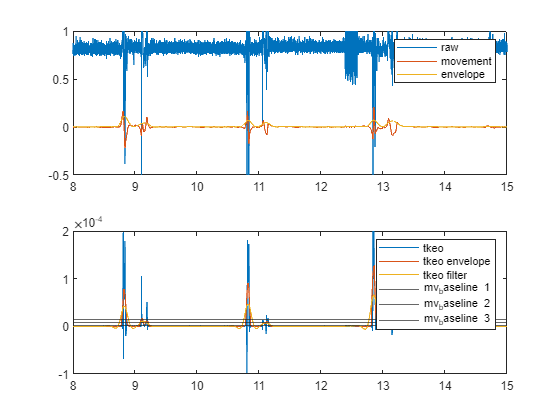

x = [8,15];
y = [-0.5,1];
y_tk = [-1e-4,2e-4];
units = ['t(s)', 'power', 'acceleration(m/s^2)'];

figure();
ch = 3;
subplot(2,1,1);
plot(t, accelerometer.channels{ch}.data, t, movement(:,ch), t, movement_envelope(:,ch))
legend('raw','movement','envelope');
xlim(x);
ylim(y);

subplot(2,1,2);
plot(t, tkeo_movement(:,ch), t, tkeo_movement_envelope(:,ch), t, tkeo_movement_filter_envelope(:,ch));
yline(mv_baseline(ch));
yline(mv_baseline(ch) + 0.5 * mv_baseline_std(ch));
yline(mv_baseline(ch) + 1 * mv_baseline_std(ch));
legend('tkeo', 'tkeo envelope', 'tkeo filter', 'mv_baseline 1', 'mv_baseline 2', 'mv_baseline 3');
xlim(x);
ylim(y_tk);

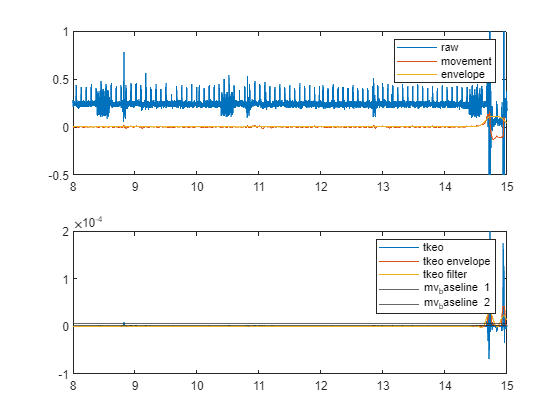


figure();
ch = 5;
subplot(2,1,1);
plot(t, accelerometer.channels{ch}.data, t, movement(:,ch), t, movement_envelope(:,ch))
legend('raw','movement','envelope');
xlim(x);
ylim(y);

subplot(2,1,2);
plot(t, tkeo_movement(:,ch), t, tkeo_movement_envelope(:,ch), t, tkeo_movement_filter_envelope(:,ch));
yline(mv_baseline(ch));
yline(mv_baseline(ch) + 0.5 * mv_baseline_std(ch));
legend('tkeo', 'tkeo envelope', 'tkeo filter', 'mv_baseline 1', 'mv_baseline 2');
xlim(x);
ylim(y_tk);

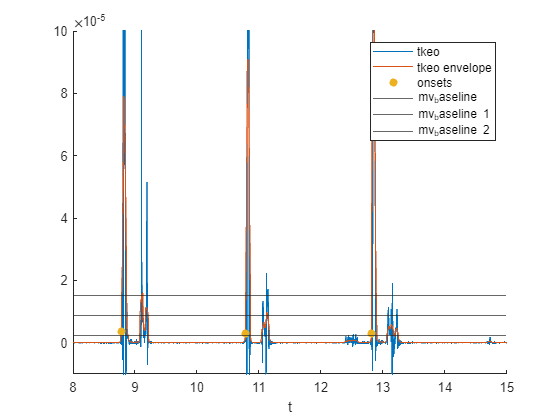

x = [8,15];
y_tk = [-0.1e-4,1e-4];
y = [-0.2, 1];

figure();
ch = 3;
hold on
plot(t, tkeo_movement(:,ch), t, tkeo_movement_envelope(:,ch));
scatter(t(mv_onset_indexes{ch}), tkeo_movement_envelope(mv_onset_indexes{ch}, ch), 'filled', 'o');
hold off
yline(mv_baseline(ch));
yline(mv_baseline(ch) + mv_baseline_std(ch));
yline(mv_baseline(ch) + 0.5 * mv_baseline_std(ch));
legend('tkeo', 'tkeo envelope', 'onsets', 'mv_baseline', 'mv_baseline 1', 'mv_baseline 2');
xlabel(units(1));
xlim(x);
ylim(y_tk);

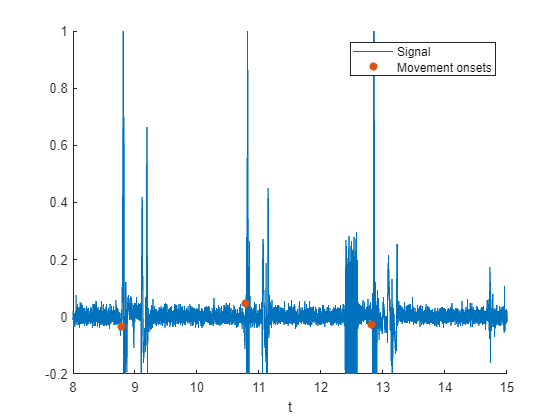


figure();
ch = 3;
hold on
plot(t, raw(:,ch));
scatter(t(mv_onset_indexes{ch}), raw(mv_onset_indexes{ch}, ch), 'filled', 'o');
hold off
legend('Signal', 'Movement onsets');
xlabel(units(1));
xlim(x);
ylim(y);

# Isolating vibration

% Isolating vibration at 120-130 Hz
cutoff_low = 120; 
cutoff_high = 130; 
filter_order = 6;

[b, a] = butter(filter_order, [cutoff_low/(sampling/2), cutoff_high/(sampling/2)], 'bandpass');

vibration = zeros(data_length, length(accelerometer.channels));
for i = 1:length(accelerometer.channels)
    vibration(:,i) = abs(filtfilt(b, a , accelerometer.channels{i}.data));
end

% TKEO https://www.ncbi.nlm.nih.gov/pmc/articles/PMC2945630/
window_size = 0.05*sampling;
[tkeo_vibration, tkeo_vibration_envelope] = getCleanSignal_tkeo(vibration, window_size, channel_nbr);

% normalize vibration and movement sizes
ratio_vb_mv = mean(tkeo_vibration_envelope) ./ mean(tkeo_movement_envelope);
tkeo_vibration_envelope = tkeo_vibration_envelope - tkeo_movement_envelope .* ratio_vb_mv;

## Finding vibration onsets

% Find signal mv_baseline
vb_baseline = mean(tkeo_vibration_envelope);
vb_baseline_std = std(tkeo_vibration_envelope);
vb_baseline_th = vb_baseline + 0.7 * vb_baseline_std;

no_onset_period_ms = 1800; % absolute no onset after time

vb_onset_indexes = getSignalOnset(tkeo_vibration_envelope, vb_baseline_th, no_onset_period_ms, channel_nbr, 1);

vb_onset_times = {};
for i = 1:channel_nbr
    vb_onset_times{i} = t(vb_onset_indexes{i});
end

## Checking that vibrations are always behind the movement

% disp(length(vb_onset_times{1}))

    89



% disp(length(vb_onset_times{2}))

   112



% disp(length(vb_onset_times{3}))

   120



% disp(length(vb_onset_times{4}))

   116



% disp(length(vb_onset_times{5}))

   109



% disp(length(vb_onset_times{6}))

   116



% 
% for i = 1:channel_nbr
%     temp = vb_onset_times;
%     for j = 1:length(temp)
%         distance = vb_onset_times{i} - mv_onset_times{i}(j);
%         vibration_after_movement = find(distance >= 0 & distance < 1.5);
% 
%         if ~isempty(vibration_after_movement)
%             temp{i}(j) = [];
%             vb_onset_indexes{i}(j) = [];
%         end
%     end
% end
% vb_onset_times = temp;
% 
% clear('temp', 'distance','vibration_after_movement');
% disp(length(vb_onset_times{1}))

    89



% disp(length(vb_onset_times{2}))

   112



% disp(length(vb_onset_times{3}))

   120



% disp(length(vb_onset_times{4}))

   116



% disp(length(vb_onset_times{5}))

   109



% disp(length(vb_onset_times{6}))

   114



# Plotting vibration

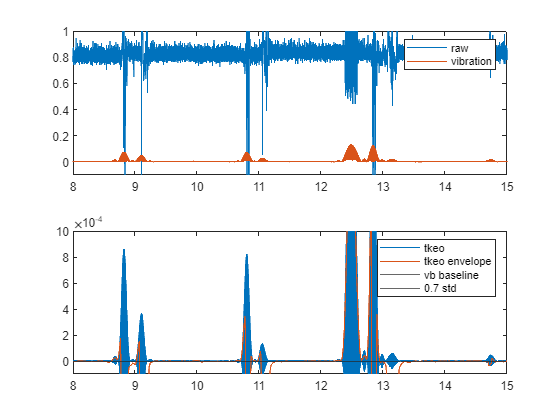

x = [8,15];
y = [-0.1,1];
y_tk = [-1e-4,10e-4];
units = ['t(s)', 'power', 'acceleration(m/s^2)'];

figure();
ch = 3;
subplot(2,1,1);
plot(t, accelerometer.channels{ch}.data, t, vibration(:,ch))
legend('raw','vibration');
xlim(x);
ylim(y);

subplot(2,1,2);
plot(t, tkeo_vibration(:,ch), t, tkeo_vibration_envelope(:,ch));
yline(vb_baseline(ch));
yline(vb_baseline(ch) + 0.7 * vb_baseline_std(ch));
yline(vb_baseline(ch) + 0.75 * vb_baseline_std(ch));
legend('tkeo', 'tkeo envelope', 'vb baseline', '0.7 std');
xlim(x);
ylim(y_tk);

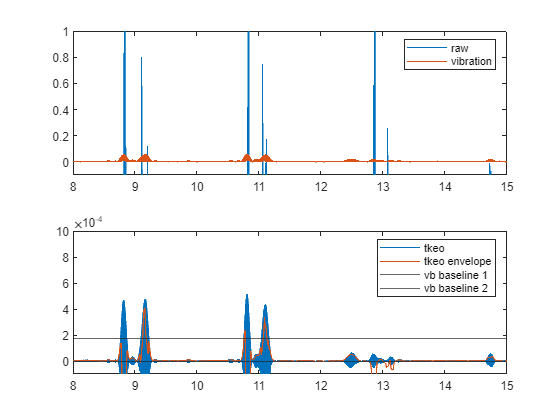


figure();
ch = 1;
subplot(2,1,1);
plot(t, accelerometer.channels{ch}.data, t, vibration(:,ch))
legend('raw','vibration');
xlim(x);
ylim(y);

subplot(2,1,2);
plot(t, tkeo_vibration(:,ch), t, tkeo_vibration_envelope(:,ch));
yline(vb_baseline(ch));
yline(vb_baseline(ch) + 0.5 * vb_baseline_std(ch));
legend('tkeo', 'tkeo envelope', 'vb baseline 1', 'vb baseline 2');
xlim(x);
ylim(y_tk);

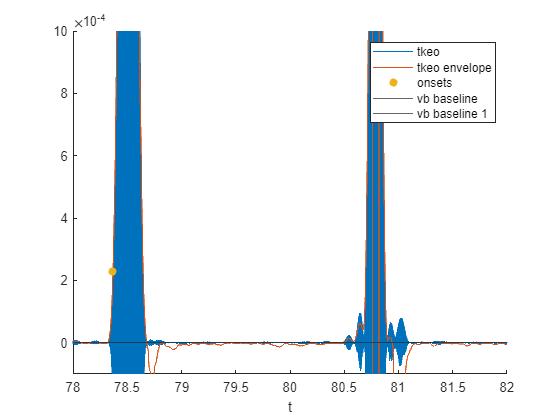

x = [78,82];
y = [-0.1,1];
y_tk = [-1e-4,10e-4];

figure();
ch = 3;
hold on
plot(t, tkeo_vibration(:,ch), t, tkeo_vibration_envelope(:,ch));
scatter(t(vb_onset_indexes{ch}), tkeo_vibration_envelope(vb_onset_indexes{ch}, ch), 'filled', 'o');
hold off
yline(vb_baseline(ch));
yline(vb_baseline(ch) + 0.7 * vb_baseline_std(ch));
legend('tkeo', 'tkeo envelope', 'onsets', 'vb baseline', 'vb baseline 1');
xlabel(units(1));
xlim(x);
ylim(y_tk);

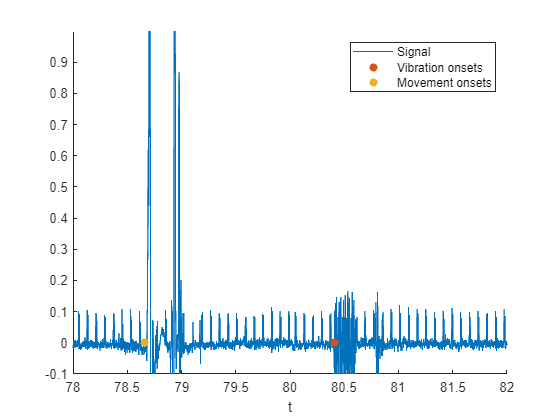


figure();
ch = 3;
hold on
plot(t, raw(:,3));
scatter(t(vb_onset_indexes{ch}), raw(vb_onset_indexes{ch}, ch), 'filled', 'o');
scatter(t(mv_onset_indexes{ch}), raw(mv_onset_indexes{ch}, ch), 'filled', 'o');
hold off
legend('Signal', 'Vibration onsets', 'Movement onsets');
xlabel(units(1));
xlim(x);
ylim(y);

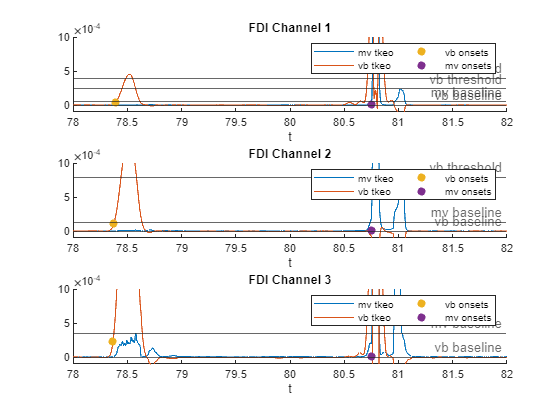

% Plot all onsets together
x = [78,82];
y = [-0.1,1];
y_tk = [-1e-4,10e-4];

figure();
for i = 1:3
    subplot(3,1,i);
    ch = i;
    hold on
    plot(t, tkeo_movement_envelope(:,ch)*ratio_vb_mv(ch), t, tkeo_vibration_envelope(:,ch));
    scatter(t(vb_onset_indexes{ch}), tkeo_vibration_envelope(vb_onset_indexes{ch}, ch), 'filled', 'o');
    scatter(t(mv_onset_indexes{ch}), tkeo_movement_envelope(mv_onset_indexes{ch}, ch), 'filled', 'o');
    hold off
    yline(vb_baseline(ch),'-', 'vb baseline');
    yline(vb_baseline(ch) + 0.7 * vb_baseline_std(ch), '-', 'vb threshold');
    yline(mv_baseline(ch)*ratio_vb_mv(ch), '-', 'mv baseline');
    yline((mv_baseline(ch) + mv_baseline_std(ch))*ratio_vb_mv(ch), '-', 'mv threshold');
    legend({'mv tkeo', 'vb tkeo', 'vb onsets', 'mv onsets'}, 'NumColumns', 3);
    title("FDI Channel " + i)
    xlabel(units(1));
    xlim(x);
    ylim(y_tk);
end

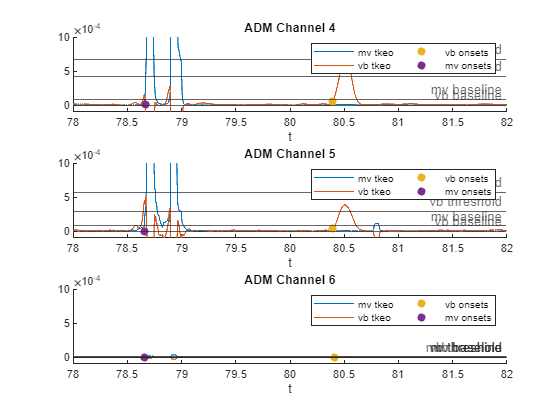


figure();
for i = 4:6
    subplot(3,1,i-3);
    ch = i;
    hold on
    plot(t, tkeo_movement_envelope(:,ch)*ratio_vb_mv(ch), t, tkeo_vibration_envelope(:,ch));
    scatter(t(vb_onset_indexes{ch}), tkeo_vibration_envelope(vb_onset_indexes{ch}, ch), 'filled', 'o');
    scatter(t(mv_onset_indexes{ch}), tkeo_movement_envelope(mv_onset_indexes{ch}, ch), 'filled', 'o');
    hold off
    yline(vb_baseline(ch),'-', 'vb baseline');
    yline(vb_baseline(ch) + 0.7 * vb_baseline_std(ch), '-', 'vb threshold');
    yline(mv_baseline(ch)*ratio_vb_mv(ch), '-', 'mv baseline');
    yline((mv_baseline(ch) + mv_baseline_std(ch))*ratio_vb_mv(ch), '-', 'mv threshold');
    legend({'mv tkeo', 'vb tkeo', 'vb onsets', 'mv onsets'}, 'NumColumns', 3);
    title("ADM Channel " + i)
    xlabel(units(1));
    xlim(x);
    ylim(y_tk);
end

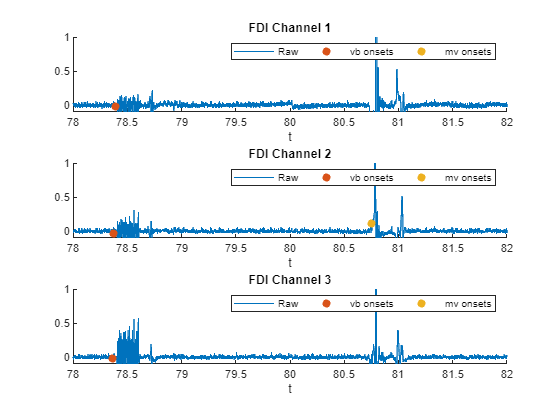

% Plot all raw
x = [78,82];
y = [-0.1,1];

figure();
for i = 1:3
    subplot(3,1,i);
    ch = i;
    hold on
    plot(t, raw(:,ch));
    scatter(t(vb_onset_indexes{ch}), raw(vb_onset_indexes{ch}, ch), 'filled', 'o');
    scatter(t(mv_onset_indexes{ch}), raw(mv_onset_indexes{ch}, ch), 'filled', 'o');
    hold off
    legend({'Raw', 'vb onsets', 'mv onsets'}, 'NumColumns', 3);
    title("FDI Channel " + i)
    xlabel(units(1));
    xlim(x);
    ylim(y);
end

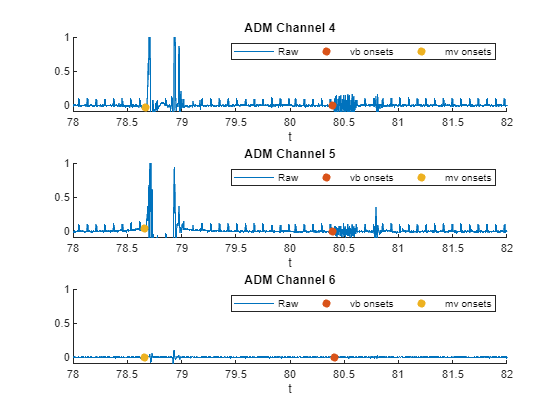


figure();
for i = 4:6
    subplot(3,1,i-3);
    ch = i;
    hold on
    plot(t, raw(:,ch));
    scatter(t(vb_onset_indexes{ch}), raw(vb_onset_indexes{ch}, ch), 'filled', 'o');
    scatter(t(mv_onset_indexes{ch}), raw(mv_onset_indexes{ch}, ch), 'filled', 'o');
    hold off
    legend({'Raw', 'vb onsets', 'mv onsets'}, 'NumColumns', 3);
    title("ADM Channel " + i)
    xlabel(units(1));
    xlim(x);
    ylim(y);
end

# Find out if FDI or ADM

## Get unique fdi and adm onsets

% Vibration
unique_fdi_vb = unique([vb_onset_times{1}, vb_onset_times{2}, vb_onset_times{3}]);
unique_adm_vb = unique([vb_onset_times{4}, vb_onset_times{5}, vb_onset_times{6}]);

unique_fdi_vb = getUniqueOnsets(unique_fdi_vb, no_onset_period_ms);
unique_adm_vb = getUniqueOnsets(unique_adm_vb, no_onset_period_ms);

discarded = [];
temp = unique_fdi_vb;
for i = 1:length(unique_fdi_vb) % TODO: function this. Find out ADM or FDI. Response box
    consensus = 0;
    if any(abs(unique_fdi_vb(i) - vb_onset_times{1}) < 0.2) 
        consensus = consensus + 1;
    end
    if any(abs(unique_fdi_vb(i) - vb_onset_times{2}) < 0.2) 
        consensus = consensus + 1;
    end
    if any(abs(unique_fdi_vb(i) - vb_onset_times{3}) < 0.2) 
        consensus = consensus + 1;
    end

    if consensus < 2 
        discarded = [discarded, i];
        temp(i) = [];
    end
end
unique_fdi_vb = temp;
discarded

discarded =      2     3     4     5     8    12    13    22    38    41    57    99   102   105



% Movement
unique_fdi_mv = unique([mv_onset_times{1}, mv_onset_times{2}, mv_onset_times{3}]);
unique_adm_mv = unique([mv_onset_times{4}, mv_onset_times{5}, mv_onset_times{6}]);

unique_fdi_mv = getUniqueOnsets(unique_fdi_mv, no_onset_period_ms);
unique_adm_mv = getUniqueOnsets(unique_adm_mv, no_onset_period_ms);

## Filter if the movement is detected in at least 2 cases